efficiencyA = 'C:\Users\maran\MATLAB Drive\thesisFinal\Results\oCRefficiency.csv'

efficiencyA = 'C:\Users\maran\MATLAB Drive\thesisFinal\Results\oCRefficiency.csv'


M = csvread(efficiencyA)

M =          0         0
    0.2000         0
    0.4000    0.0012
    0.6000         0
    0.8000         0
    1.0000    0.0008
    1.2000         0
    1.4000         0
    1.6000         0
    1.8000         0


x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =          0
         0
    0.0012
         0
         0
    0.0008
         0
         0
         0
         0



sOne = rms(y(15:115,:))

sOne = 0.0694

sTwo = rms(y(165:275,:))

sTwo = 0.0907

sThr = rms(y(315:415,:))

sThr = 0.0871

%sFour = rms(y(271:290,:))
sM = [sOne sTwo sThr]

sM =     0.0694    0.0907    0.0871



speed = string(round(rms(sM),2, 'significant'))

speed = "0.083"

sD = num2str(std(sM),'%.1E')

sD = '1.1E-02'

speed = 'Average '  + speed +' '+ char(177) + ' ' + sD

speed = "Average 0.083 ± 1.1E-02"

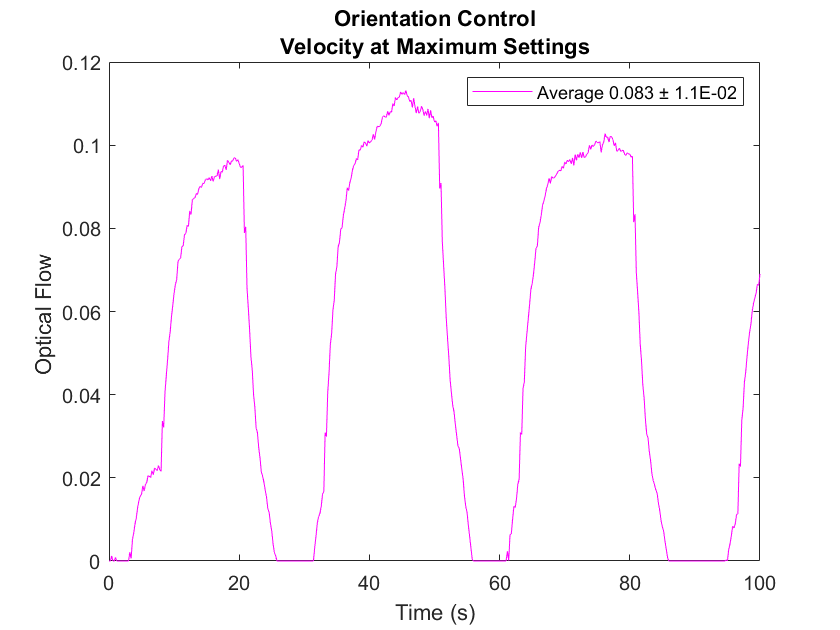


f = plot(x,y,'m');
xlabel('Time (s)');
ylabel('Optical Flow ');
title({'Orientation Control'; 'Velocity at Maximum Settings'})
legend({speed},'Location','northeast')